# Übung 4

## 4.1 Startup

Stellen Sie durch zwei geeignete Matlab-Befehle sicher, dass

- der Workspace initialisiert ist,

- alle Figures (Diagrammfenster) geschlossen sind und

- die Darstellung der Ergebnisse 'compact', also ohne zusätzliche Leerzeilen erfolgt.

close all
clear all
clc
format compact

Im Folgenden ergänzen/erweitern Sie dieses Script. Sofern nicht anders angegeben, unterdrücken Sie die Ergebnisausgabe (Strichpunkt am Zeilenende). Wenn Sie alle Übungsaufgaben bearbeitet haben, publizieren ('publishen') Sie das Skript als PDF. Geben Sie dieses PDF (und nur dieses PDF) zur Kontrolle ab (moodle/Laufwerk/email).

## 4.2 Schaltungsanalyse

Gegeben sei folgende Schaltung

%figure
%img1 = imread('rlc.png');
%img1 = imresize(img1, 0.33);
%imshow(img1);

mit *R1*= 10kOhm, *Rs*= 1Ohm, *L1*= 16µH, *C1*= *C2* = 3.3nF und u= 1Vrms.

Hinweis: *Rs* ist integraler Bestandteil der Induktivität *L* und soll in der Impedanz der Induktivität berücksichtigt werden.

Defininieren Sie die Variablen *R1*, *L1*, *C1*, *C2* und U. Weisen Sie die entsprechenden Werte zu.

% https://www.google.com/search?sca_esv=601437379&rlz=1C1YTUH_deDE1079DE1079&sxsrf=ACQVn09GjjpHv0JhYz37i9kLDY_aHgtD8A:1706199089238&q=micro+nano&tbm=isch&source=lnms&sa=X&ved=2ahUKEwjW5IT19viDAxVM_7sIHWH0ALYQ0pQJegQICxAB&biw=1536&bih=742&dpr=1.25#imgrc=z78N9RPpRruWGM
R1 = 10000 % Ohm

R1 = 10000

Rs = 1 % Ohm

Rs = 1

L1 = 16 * 10^-6 % microhenry

L1 = 1.6000e-05

C1 = 3.3 * 10^-9 % nanofarad

C1 = 3.3000e-09

C2 = 3.3 * 10^-9 % nanofarad

C2 = 3.3000e-09

u = 1 % 1 Vrms

u = 1

## 4.3 Effektive Kapazität

Berechnen Sie die effektive (in der Schaltung wirksame) Kapazität *C*.

Ceff = C1*C2/(C1+C2);

## 3.4 Resonanzfrequenz

Berechnen Sie die Resonanzfrequenz des Schwingkreises (das ist diejenige Frequenz bei der *Zl* = *Zc* ist.

Betrag von Zl ist gleich Betrag von Zc

2*pi*f*L = 1 / 2*pi*f*c <=> f = 1/ (2*pi*sqrt(L*C))

Gedanke: Gleichung nach f umstellen. f ist dann die resonanzfrequenz.

fres = 1 / ( 2 * pi * sqrt(L1 * Ceff))

fres = 9.7953e+05

Benutzen Sie die Funktion *fprintf* um die Resonanzfrequenz mit drei Nachkommastellen in MHz auszugeben

fprintf(['fres = %.3f MHz\n'], fres/1e6);

fres = 0.980 MHz


## 4.5 Qüte und Bandbreite

Die Güte eines Parallelschwingkreises ist gegeben durch

$$ Q = R \sqrt{ \frac{C}{L} } $$,

die Bandbreite durch

$$ B = \frac{fres}{Q} $$.

Berechnen Sie Güte und Bandbreite für den gegeben Kreis.

zL_seriell = Rs + j*2*pi*fres*L1;
zL_p = 1 / (zL_seriell);
zL_parallel = 1 / (imag(zL_p));
Rp = 1 / real(zL_p);

Q = Rp * sqrt(Ceff / L1)

Q = 98.4833

B = fres / Q

B = 9.9462e+03

## 4.6 Impedanzen

Berechnen Sie die Impedanzen *zL* und *zC* für *f*=100kHz .. 10MHz. Verwenden Sie zur Erzeugung des Frequenzenvektors die Funktion *logspace* mit 10.000 Punkten.

fx = logspace(5, 7, 10000); % 3 und 6 sind die Exponenten!!!
zL = j*2*pi*fx*L1 + Rs;
zCeff = 1 ./ (j*2*pi*fx*Ceff);

Plotten Sie die Beträge der Impedanzen *zL* und *zC* in ein neues Diagramm. Stellen Sie das Ergebnis halblogarithmisch dar (*semilogx*). Beschriften Sie die Achsen und verwenden Sie eine Legende.

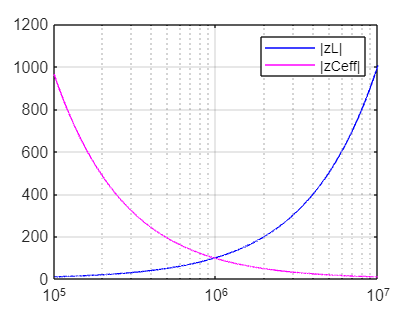

figure
semilogx(fx, abs(zL), 'b-');
hold on
semilogx(fx, abs(zCeff), 'm-');
grid on
legend('|zL|', '|zCeff|');

Berechnen Sie nun die Gesamtimpedanz *zG*, die an die Spannungsquelle angeschlossen ist.

zG = zL .* zCeff ./ (zL + zCeff)

zG = 1.0e+03 *

   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0102i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0103i   0.0010 + 0.0104i   0.0010 + 0.0104i   0.0010 + 0.0104i   0.0010 + 0.0104i   0.0010 + 0.0104i   0.0010 + 0.0104i   0.0010 + 0.0104i   0.0010 + 0.0104i   0.0010 + 0.0104i   0.0010 + 0.0104i


Plotten Sie den Betrag der Gesamtimpedanz *zG(f)* in ein neues Diagramm. Stellen Sie das Ergebnis halblogarithmisch dar (*semilogx*). Beschriften Sie die Achsen.

Verbessern Sie die Darstellung der Kurve, indem Sie die Frequenzachse nachskalieren (Funktion *axis*). Vorgeschlagener Bereich: fres +/- 5%. ACHTUNG: Sie müssen auch die Y-Achse manuell skalieren. Benutzen Sie hier die min- bzw. max-Funktion um die passenden Werte zu ermitteln.

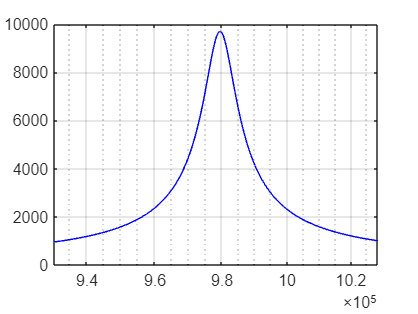

figure
semilogx(fx, abs(zG), 'b-')
axis([0.95*fres 1.05*fres 0 10e3])
grid on

Plotten Sie in einem weiteren Diagramm den Phasenverlauf der Gesamtimpedanz *zG(f)* in Grad (Funktion *angle* liefert Bogenmaß!). Auch hier bitte nachskalieren!

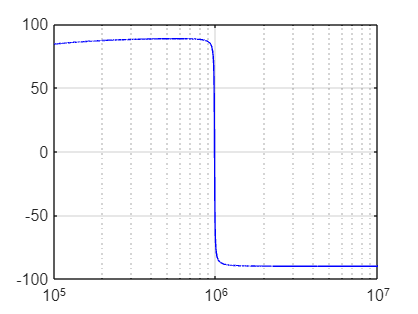

figure
semilogx(fx, angle(zG)/pi*180, 'b-')
%axis([0.95*fres 1.05*fres 0 10e3])
grid on

## 4.7 Zufließender Strom Ig

Berechnen Sie den Gesamtsrom *iG* der durch *R1* in die Schaltung fließt.

zGes = zG + R1;
iGes = u ./ zGes;

Stellen Sie den Verlauf des Strombetrages `iG(f)` in einem neuen Diagramm dar.

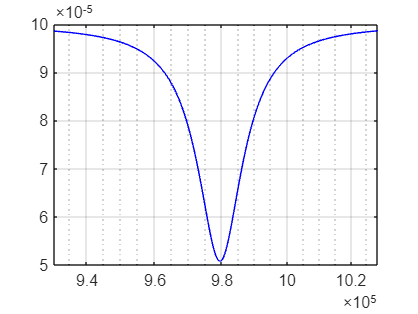

figure
semilogx(fx, abs(iGes), 'b-')
axis([0.95*fres 1.05*fres 5e-5 10e-5])
grid on

## 4.8 Spannung *Uc*

Berechnen Sie nun die Spannung an den Kapazitäten (Differenz der Spannung *U* und dem durch *iG* an *R* verursachten Spannungsabfall).

uCeff = u-iGes*R1;

Stellen Sie den Verlauf der Spannung *uC* in einem neuen Diagramm dar.

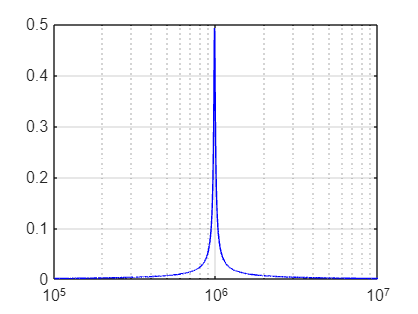

figure
semilogx(fx, abs(uCeff), 'b-')
%axis([0.95*fres 1.05*fres 5e-5 10e-5])
grid on

Erstellen Sie den Vektor *fx*, der die Kennfrequenzen (untere Grenzfrequenz, Resonanzfrequenz, obere Grenzfrequenz) des Schwingkreises enthält und den Vektor *Ux*, der die Spannungen *Uc* für diese Frequenzen enthält.

...

Markieren Sie die drei Kennpunkte im aktuellen Diagramm (Funktionen *hold* und *semilogx*). Benuzen Sie rote Kreise, um die Punkte zu markieren.

...

Plotten Sie den Phasenverlauf *uC(f)* in Grad in ein neues Diagramm .

...

Erstellen Sie den Vektor *Ax* der die Phasenwinkel für die drei Kennfrequenzen (in Grad) enthält. Markieren Sie auch diese Kennpunkte im aktuellen Diagramm mit roten Kreisen.

...

## 4.9 Ströme iL und iC

Berechnen Sie den Verlauf der Beträge der Ströme durch die Kondensatoren

%_iC(f)_ und der Spule _iL(f)_ .
...

Vergleichen Sie den in den Kreis hineinfließenden Strom mit dem im Kreis fließenden Strom bei Resonanz. Kommentieren Sie

...

Kommentar: der im Kreis fließende Strom ist bei Resonanz fast 100 mal größer als der in den Kreis hinein fließende (Stromresonanz).

## 4.10 Spannung an C1

Wie groß ist das Verhältnis der Spannungen *uC1*/_uC_, wenn der Kreis in Resonanz betrieben wird?

...

## 4.11 Überlegung

Wie groß ist die Spannung *uC* bei Resonanz, wenn die Spannungsquelle über *R* zwischen den beiden Kondensatoren eingespeist wird?

...